# (C) Actividad tracking

Lectura de datos

I=imread('../data/rechazo.png');

Detección de puntos azul y rojo

[Xred,Yred,Xblue,Yblue] = getRedBluePositions(I);

Limpieza: borrar elementos pequeño de color piel, mantener objetos azules y rojos solo si estan rodeados de color piel.

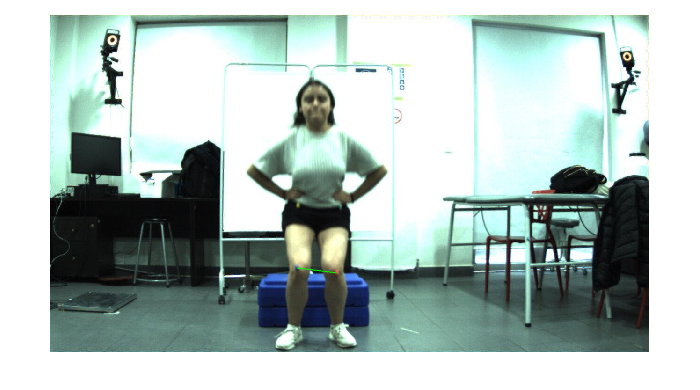

%visualizamos: imagen, el segmento de recta, y el angulo
imshow(I);
hold on,
plot([Xblue Xred], [Yblue Yred], 'g');

Ahora haremos la lectura de cada imagen del video y luego aplicaremos la detección

v = VideoReader("../data/videoejemplo.avi");
Ymarcador=zeros(v.NumFrames,1);
for i=1:v.NumFrames
    frame = read(v,i);
    [Xred,Yred,Xblue,Yblue] = getRedBluePositions(frame);
    Ymarcador(i)=Yred;
    %visualizamos: imagen, el segmento de recta, y el angulo
    %imshow(frame);
    %hold on,
    %plot([Xblue Xred], [Yblue Yred], 'g');
    %drawnow;
end

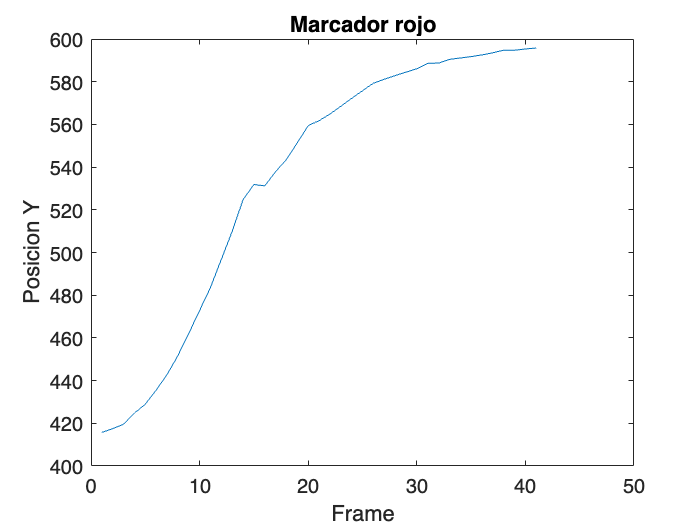

figure;
plot(Ymarcador);
xlabel('Frame');
ylabel('Posicion Y');
title('Marcador rojo')